# mm_main_fb_lin_tracking


% Closed-loop trajectory tracking for the mobile manipulator
% using feedback linearization on the reduced dynamics.
%
% State: X = [q; eta_dot]
%   q       = [x_b; y_b; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]
%   eta_dot = [theta_r_dot; theta_l_dot; theta_1_dot; theta_2_dot; theta_3_dot]
%
% Control: tau = [tau_r; tau_l; tau_1; tau_2; tau_3]

clc; clearvars; close all;

fprintf('▶ Starting mobile manipulator tracking simulation...\n');

▶ Starting mobile manipulator tracking simulation...


## 1) Paths & parameters


project_root = './';
addpath(fullfile(project_root, 'dynamics_library'));

addpath(fullfile(project_root, 'dynamics_library/mm_reference_trajectory'));

addpath(fullfile(project_root, 'data'));


fprintf('✅ Library and data paths added.\n');

✅ Library and data paths added.



% Load physical parameters
[phys, move] = mm_params_build_save_load('load', 'mm_params');

Loaded: mm_params.mat


fprintf('✅ Physical parameters loaded.\n');

✅ Physical parameters loaded.


## 2) Controller gains (η-level PD in the feedback-linearized system)


ctrl = struct();
ctrl.phys = phys;

% Tune these
% Kp_eta = diag([ 40  40  30  30  30 ]);
% % Kd_eta = diag([ 10  10   8   8   8 ]);
% Kp_eta = diag([ 4  4  3  3  3 ]);
% Kd_eta = diag([ 1  1   0.8   0.8   0.8 ]);
Kp_eta = diag([ 4  4  3  3  3 ]);
Kd_eta = diag([ 3  3   2   2   2 ]);
ctrl.Kp = Kp_eta;
ctrl.Kd = Kd_eta;


## 3) Simulation horizon


Tf   = 10.0;          % [s]
dt_plot = 0.01;       % for reference evaluation / plotting


## 4) Initial state X0 (NOT equal to reference at t=0 on purpose)

% Use realistic initial conditions
% Joint angles in [−π,π] or within actual joint limits.
% Velocities in a realistic range (e.g. ∣θ˙∣<2 rad/s). (< 19.1 revolutions per minute RPM)
% q = [x_b; y_b; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]
% q0 = [ ...
%     -0.30;   % x_b(0)  [m]
%      0.20;   % y_b(0)  [m]
%      0.30;   % theta_m(0) [rad]
%      0.50;   % theta_r(0) [rad]
%     -0.40;   % theta_l(0) [rad]
%      0.20;   % theta_1(0) [rad]
%     -0.30;   % theta_2(0) [rad]
%      0.10];  % theta_3(0) [rad]
% 
% % Wheel/joint velocities initial
% eta_dot0 = [ ...
%      0.20;   % theta_r_dot(0)
%     -0.10;   % theta_l_dot(0)
%      0.00;   % theta_1_dot(0)
%      0.00;   % theta_2_dot(0)
%      0.00];  % theta_3_dot(0)

q0 = [ ...
    0;   % x_b(0)  [m]
     0;   % y_b(0)  [m]
     0;   % theta_m(0) [rad]
     0;   % theta_r(0) [rad]
    0;   % theta_l(0) [rad]
     0.5;   % theta_1(0) [rad]
    -0.7;   % theta_2(0) [rad]
     2.1];  % theta_3(0) [rad]

% Wheel/joint velocities initial
eta_dot0 = [ ...
     0;   % theta_r_dot(0)
    0;   % theta_l_dot(0)
     0.3;   % theta_1_dot(0)
     1.2;   % theta_2_dot(0)
     0.2];  % theta_3_dot(0)
X0 = [q0; eta_dot0];

fprintf('ℹ️  Initial state X0 is intentionally different from reference.\n');

ℹ️  Initial state X0 is intentionally different from reference.


## 5) Define controller handle and closed-loop dynamics


% u_fun(t,q,eta_dot) -> tau
u_fun = @(t, q, eta_dot) mm_fb_lin_controller(t, [q; eta_dot], ctrl);

% RHS for ODE: dX/dt = f(t, X)
f_cl = @(t, X) mm_closed_loop_rhs(t, X, u_fun);


## 6) Integrate closed-loop dynamics


fprintf('▶ Integrating dynamics with ode45...\n');

▶ Integrating dynamics with ode45...


ode_opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
[t, X] = ode45(f_cl, [0 Tf], X0, ode_opts);

fprintf('✅ Simulation finished. Number of steps: %d\n', numel(t));

✅ Simulation finished. Number of steps: 341


## 7) Re-compute control efforts tau(t) along trajectory


fprintf('▶ Recomputing control efforts along the trajectory...\n');

▶ Recomputing control efforts along the trajectory...


N = numel(t);
U = zeros(N, 5);  % [tau_r, tau_l, tau_1, tau_2, tau_3]

for k = 1:N
    q_k       = X(k, 1:8).';    % 8x1
    eta_dot_k = X(k, 9:13).';   % 5x1
    tau_k     = u_fun(t(k), q_k, eta_dot_k);
    U(k, :)   = tau_k(:).';     % row
end
fprintf('✅ Control efforts computed.\n');

✅ Control efforts computed.


## 8) Compute desired trajectories for plotting (η and base)


fprintf('▶ Computing desired trajectories for reference plotting...\n');

▶ Computing desired trajectories for reference plotting...


t_dense = (0:dt_plot:Tf).';
Nd = numel(t_dense);

eta_d_all      = zeros(Nd, 5);
eta_dot_d_all  = zeros(Nd, 5);
eta_ddot_d_all = zeros(Nd, 5);

for k = 1:Nd
    [eta_d_k, eta_dot_d_k, eta_ddot_d_k] = desired_eta_law(t_dense(k), phys);
    eta_d_all(k, :)      = eta_d_k(:).';
    eta_dot_d_all(k, :)  = eta_dot_d_k(:).';
    eta_ddot_d_all(k, :) = eta_ddot_d_k(:).';
end

fprintf('✅ Desired trajectories computed.\n');

✅ Desired trajectories computed.


## 9) Plot results (states & control efforts)

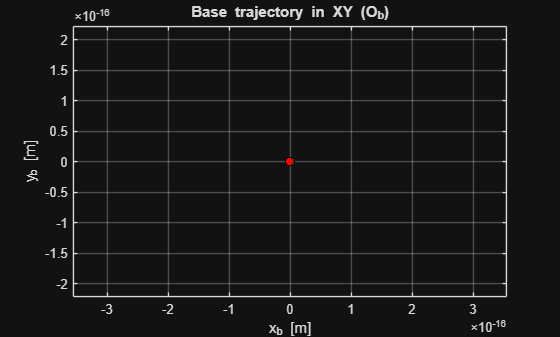

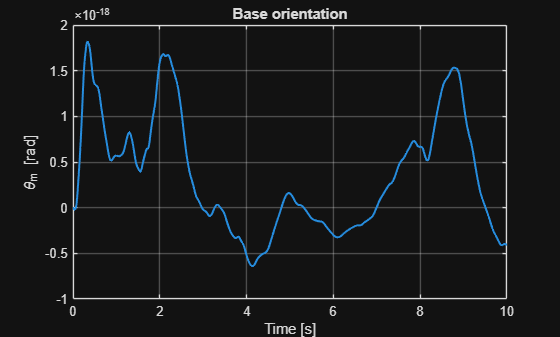

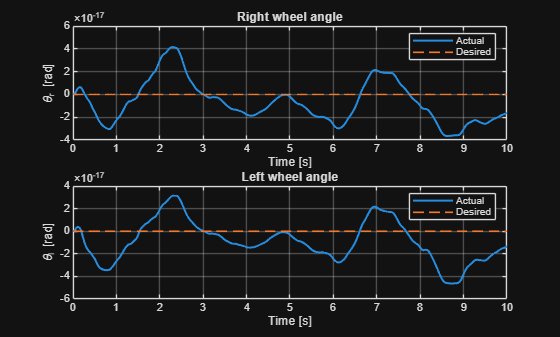

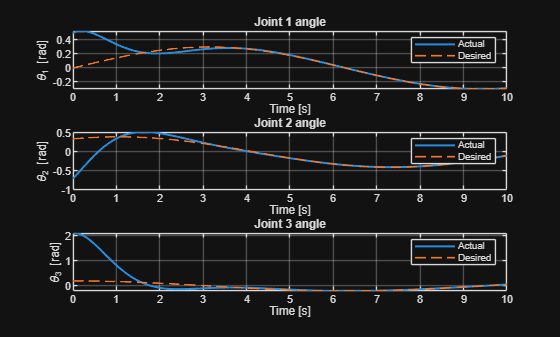

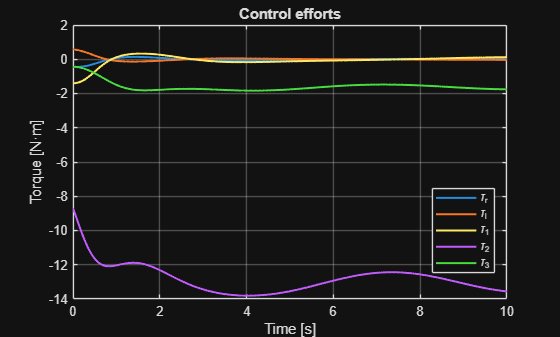


mm_plot_results(t, X, t_dense, eta_d_all, U);


fprintf('🏁 Done.\n');

🏁 Done.
